## Circular Piston Transducer

This example shows the beam pattern for a baffled circle piston, an approximation to the a circular piston transducer.

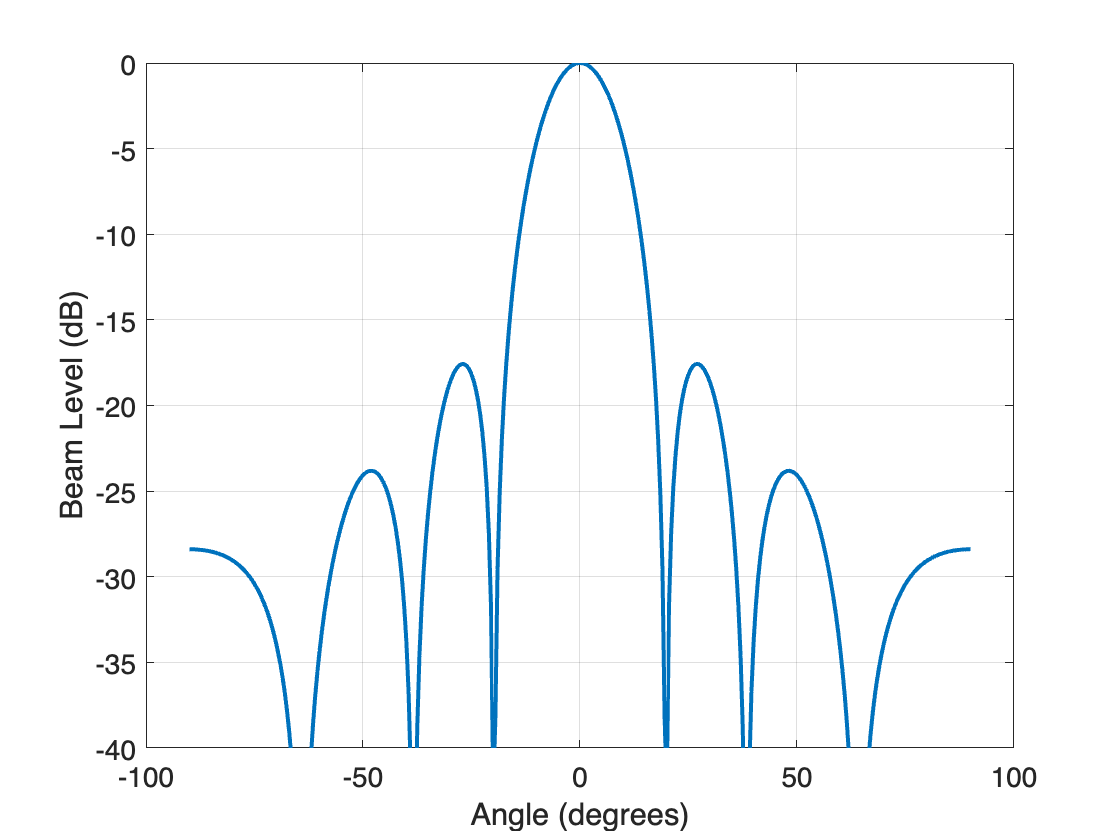

f = 9;      % Frequency in kHz
rho0 = 1;
c = 1500;
a = 0.3;
r = 10;

omega = 2*pi*f*1000;
k = omega/c;

theta = -90:0.5:90;
u = k*a*sin(theta*pi/180);

projInt = abs((rho0*c*k*a*a/(2*r)).*...
    (2*besselj(1,u)./u)).^2;
ind = find(theta == 0);
axisInt = abs(rho0*c*k*a*a/(2*r)).^2;
projInt(ind) = axisInt;

plotType = 0;
plotScale = "Decibels";

if plotType == 0

    if plotScale == 'Decibels'

        plot(theta,10*log10(projInt/axisInt),'linewidth',2)
        a1 = gca;
        a1.YLim = [-40 0];
        a1.FontSize = 14;
        a1.XLabel.String = 'Angle (degrees)';
        a1.YLabel.String = 'Beam Level (dB)';
        grid on

    else

        plot(theta,projInt/axisInt,'linewidth',2)
        a1 = gca;
        a1.YLim = 10.^([-40 0]/10);
        a1.FontSize = 14;
        a1.XLabel.String = 'Angle (degrees)';
        a1.YLabel.String = 'Beam Level';

    end


elseif plotType == 1

    if plotScale == 'Decibels'

        polarplot(theta*pi/180,10*log10(projInt/axisInt),'linewidth',2)
        a1 = gca;
        a1.RLim = [-40 0];
        a1.ThetaZeroLocation = 'top';
        a1.ThetaLim = [-90 90];
        a1.Title.String = 'Beam Pattern (dB)';
        a1.FontSize = 14;

    else

        polarplot(theta*pi/180,projInt/axisInt,'linewidth',2)
        a1 = gca;
        a1.RLim = 10.^([-40 0]/10);
        a1.ThetaZeroLocation = 'top';
        a1.ThetaLim = [-90 90];
        a1.Title.String = 'Beam Pattern (Linear Scale)';
        a1.FontSize = 14;

    end

end

ind3dB = find(10*log10(projInt/axisInt) >= -3);
ind6dB = find(10*log10(projInt/axisInt) >= -6);
ind10dB = find(10*log10(projInt/axisInt) >= -10);

bw3dB = abs(theta(ind3dB(1)));
bw6dB = abs(theta(ind6dB(1)));
bw10dB = abs(theta(ind10dB(1)));

bwLabels = {'down 3dB';'down 6 dB';'down 10 dB'};
bwValues = [bw3dB; bw6dB; bw10dB];
varNames = {'Beam Width (degrees)';' '};

T = table(bwValues,bwLabels,'VariableNames',varNames);
display(T)

T = 3×2 table
    Beam Width (degrees)                  
    ____________________    ______________

               8            {'down 3dB'  }
              11            {'down 6 dB' }
            13.5            {'down 10 dB'}


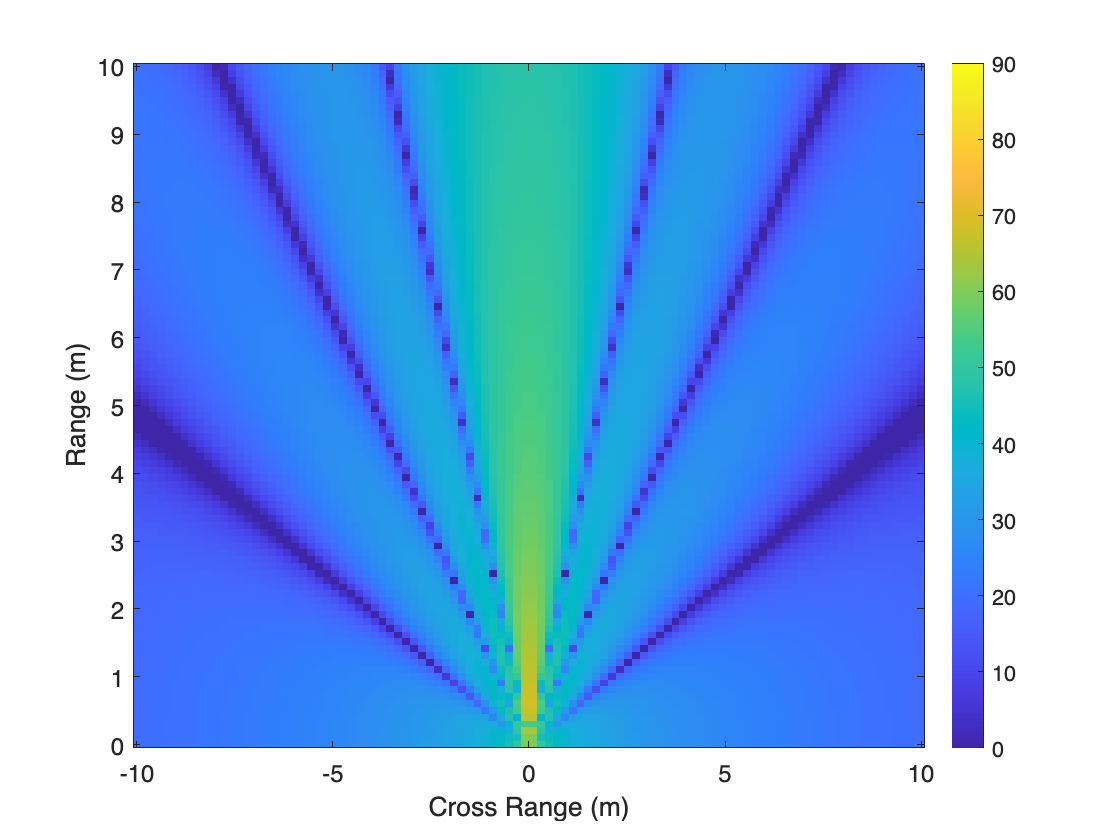

x = linspace(-r,r,100);
y = linspace(0,r,100);

[X,Y] = meshgrid(x,y);

thetaXY = atan2(X,Y);
rXY = sqrt(X.^2 + Y.^2);
u1 = k.*a.*sin(thetaXY);
projIntXY = abs((rho0*c*k*a*a./(2*rXY)).*...
    (2*besselj(1,u1)./u1)).^2;

if plotScale == 'Decibels'
    imagesc(x,y,10*log10(projIntXY))
    a2 = gca;
    a2.YDir = 'normal';
    colorbar
    a2.FontSize = 12;
    a2.CLim = [0 90];
    a2.XLabel.String = 'Cross Range (m)';
    a2.YLabel.String = 'Range (m)';
else
   imagesc(x,y,projIntXY)
    a2 = gca;
    a2.YDir = 'normal';
    colorbar
    a2.FontSize = 12;
    a2.CLim = 10.^([0 60]/10); 
    a2.XLabel.String = 'Cross Range (m)';
    a2.YLabel.String = 'Range (m)';
end